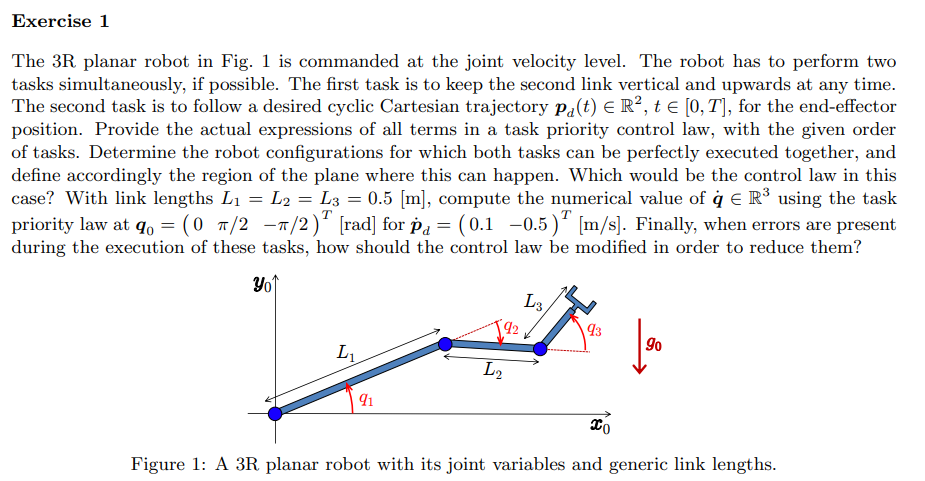

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% % m_p = sym('m_p','real');
% % m(2)=m(2)+m_p
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

s

% R2Robot=['rrr';'xxx';[1,1,1]]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.joint_on=false;

## torque regulation catesian

% % z_regulation_torque=Join_Torque_Control_Law_Regulation(z)
% 

## using Cartesian dynamics control LAw

% 
% % z_regulation_torque=cartesian_dynamics_Control_Law_Regulation(z)
% 

## dynamic model computation neccessary for the control law

% % z.task_defined={struct('Pc',q(1)+q(2),'f',sum([q(1),q(2),0]))} %pc is note necessary
% % z.taskpositions=struct('main',2,'remain',[1])
% pd={sym('pd_1_',[1,1],'real'),sym('pd_2_',[2,1],'real')};
% z.task_defined={struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0]),struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]')} %pc is note necessary
% z.xyonly=false %% should be false if we wnat to add new tasks
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% PCVar.f_dot
% PCVar.f_ddot
% PCVar.f_tdot
% PC_EEShort.J
% % f(3)=
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);
% % Trans.Jacobian_PTotal
% % Trans.Jacobian_dot_PTotal
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % cac

## rank of J

% rank(J)

% rd_1=f(1,:)
% rd_2=f(2:end,:)

## redundancy task with prioriy

% replace_values=true
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0,pi/2,-pi/2]'
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);
% 

## seein varaibles

% q_dot_k{:}
% z_task.J_k{:}
% z_task.J_k_pinv{:}
% z_task.P_A_k{:}
% 
% z_task.q_dot_k_{:}
% z_task.J_k_{:}
% z_task.J_k_pinv_{:}
% z_task.P_A_k_{:}

% r_dot_k=z_task.r_dot_k
% simplify(subs(q_dot_k{2},r_dot_k{1},0))
% simplify(simplify(pinv((z_task.J_k{2}*z_task.P_A_k{1})))*z_task.r_dot_k{2})
% 

## cheking if is possible do both tasks

% f_k_red=simplify(subs(z_task.f_k{2},q(1)+q(2),pi/2))
% q_red=[q(1),q(3)]'
% q_dot_red=[q_dot(1),q_dot(3)]'
% J_k_red=jacobian(f_k_red,q_red)
% q_dot_=q_dot;
% q_dot_(2)=-q_dot_(1)

## singularities

% simplify(det(J_k_red)) %%singular in q_1-q_3=m*pi/2 where m>0

## replacing values

% q_=[0,pi/2,-pi/2]'
% l_=[0.5,0.5,0.5]'
% r_dot_k=[z_task.r_dot_k{1};z_task.r_dot_k{2}]
% r_dot_k_=[0,0.1,-0.5]'
% vars2replace =[q ;l;r_dot_k]
% vars2replace_=[q_;l_;r_dot_k_]
% q_dot_k{2}
% q_dot_k_=subs(z_task.q_dot_k_{2},vars2replace,vars2replace_)
% term1_=subs(z_task.J_k{2}*z_task.P_A_k{1},vars2replace,vars2replace_)
% pinv(term1_)

## replacing singular values into each jacobian

% z_task.J_k{1}*q_dot_k_ %% equal to zero it means that the task can be done
% 
% subs(z_task.J_k{2}*q_dot_k_,[q;l],[q_;l_] )%% in this case it is different of the pd_dot_2 then this task s not possible to realize only with an minimization error result


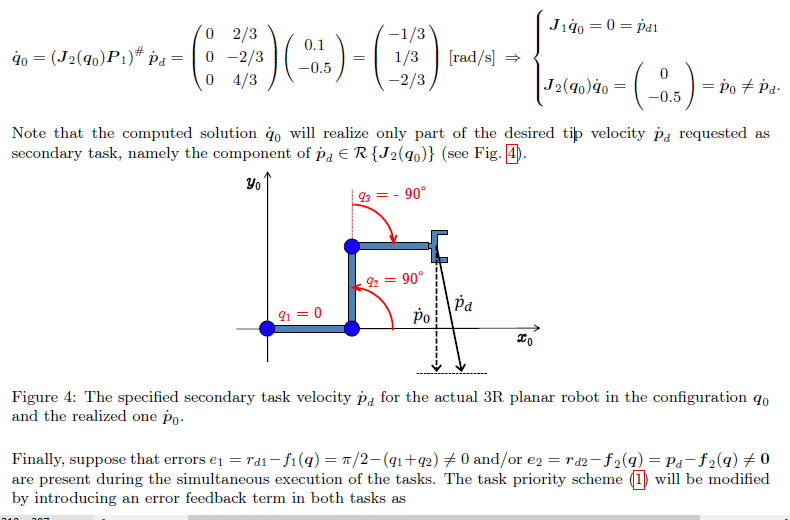

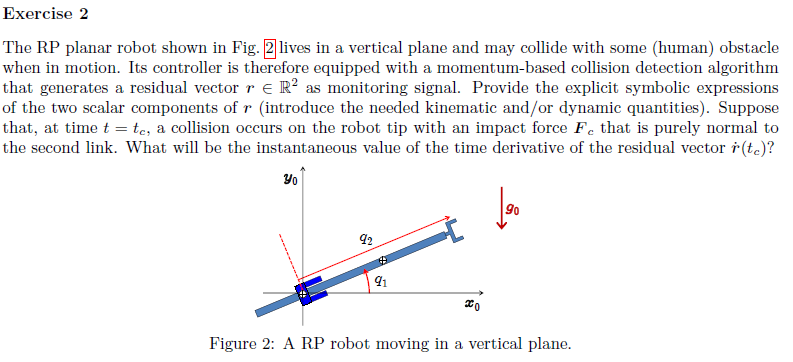

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,1]; %% rot=0 prismatic=1
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% % m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% 
% R2Robot=['rp';'xx';[1,1]]    
% 
% z = Gen_param(n);
% z.g=[0,-g0,0]';
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
%  z.opt_expr={[l(1),dc(1)],[0,0]};
% % z.rcdefined=true;

## defining collisions

% 
% % collide1=
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[-sin(q(1)),cos(q(1)),0]' ,'joint',2,'F_pos',l(2)*0), %%position force taken from the base in this case on the EE
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

## computing

% 
% % 
% %    
% % % xyonly=true
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGtenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% z.q_=[pi/2,-pi/2]';
% z.q_dot_=[0,pi/4]';
% z.l_=[1,1;]';
% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% 
% 
% M
% Ti
% J_c_collisions=zout.J_c_collisions{:}
% J_c_collisions_=zout.J_c_collisions_{:}
% Pc_collisions=zout.Pc_collisions
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% vc_=subs(vc,q,z.q_)
% 
% %% check formula and complete with this parameters
% zout.p_r
% % zout.tau
% zout.to_integrate
% % zout.r
% zout.P_0

% zout.cac
% zout.S
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % cac

## computing gravity

% % isMotor=false
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

% zout.U{:}
% zout.g_q

%  u_subs = M*q_ddot +zout.cac+ zout.g_q 

## computing the residuals r_d

%  %the nominal r_d chould be eual to 0 (no collision)
%  k_i=sym('k_i_',[2,1],'real')
%  r_c_sym=sym('r_c_',[2,1],'real')
%  tau_c_sym=sym('tau_c_',[2,1],'real')
%  r_dot_c=k_i.*(tau_c_sym-r_c_sym)
%  
%  r_dot_c_=subs(r_dot_c,r_c_sym,[0,0]')
%  r_dot_c2_=subs(r_dot_c_,tau_c_sym,zout.Tau_c)


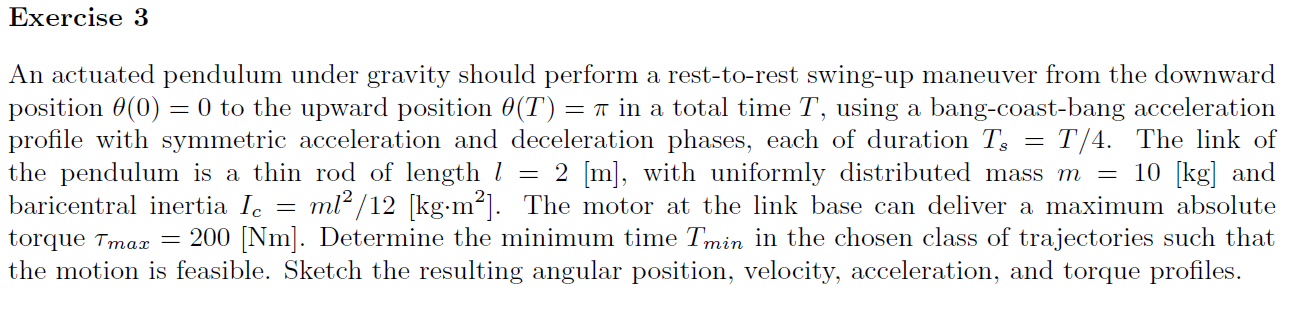

clear all, clc, close all
% This part is isolated from previous sectionclear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');

m_p = sym('m_p','real');
d = sym('d','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
% g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% g=[0,-g0*sin(alpha_angle),0]';
g=[0,0,-g0]';
R2Robot=['rp';'xx';sigma]    

R2Robot = 3×2 char array
    'rp'
    'xx'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;

z.q=q;
z.q_dot=q_dot;

z.dc=dc;

z.I=I;
z.methodD=1%with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: []
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: []
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0


% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.l=l;
 z.m=m;
z.opt_expr={[l(1),dc'],[0,0,d]};
% z.rcdefined=true;
z.prismatic_CoM_method=[1,2];1%% normal mode onle CoM=dc(i) in %% 2 inverse mdoe CoM=q(i)-dc(i) %% for the moment only for prismatics

ans = 1

## computing M

% [Pc,vc,w,T,Ti,M] = getGenericPC2(z);
% T
% Ti(:)
% M
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
% cac
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% tau =simplify( M*q_ddot + cac);
% 
% tau_=subs(tau)

% C{:}
% R=sym('R','real')
% vars2replace =[q(2);q_dot(1)]
% vars2replace_=[R;0]
% tau_=subs(tau,vars2replace,vars2replace_)

## computing maximun aceleration

clear all;
close all;
clc;
m_=10

m_ = 10

l_=2

l_ = 2

theta_T=pi;
theta_s_=theta_T/6

theta_s_ = 0.5236

I_=m_*l_^2/12

I_ = 3.3333

g_0=9.81

g_0 = 9.8100

d_=l_/2

d_ = 1

tau_g_max_=m_*g_0*d_

tau_g_max_ = 98.1000

tau_max_=200

tau_max_ = 200

sin(theta_s_)

ans = 0.5000

T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))

T_min = 0.6083

## bang cost bang profile

T=sym('T','real');
V1=sym('V1','real');
A1=sym('A1','real');
T_=1*T_min%1.2165;

T_ = 0.6083

% T_=1.2165;
Ts_=T_/4

Ts_ = 0.1521

A1_=16*pi/(3*T_^2);
Ts=T/4;
V1=Ts*A1;
V1_=Ts_*A1_;
qA=[0,1]'

qA =      0
     1


qB_=[pi,pi]'

qB_ =     3.1416
    3.1416


qB=sym('qB',[2,1],'real');

I_0=1

I_0 = 1

% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
[qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)

$$qa\_piece1 = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ 0 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ A_{1}\,\mathrm{Ts} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ A_{1}\,\mathrm{Ts}-A_{1}\,\left(\mathrm{Ts}-T+t\right) & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ -\frac{A_{1}\,\mathrm{Ts}\,\left(\mathrm{Ts}-2\,t\right)}{2} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,\mathrm{Ts}-2\,T\,t+2\,{\mathrm{Ts}}^{2}+t^{2}\right)}{2} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ 0 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ A_{1}\,\left(T-t\right) & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ \frac{V_{1}\,\left(2\,t-\frac{V_{1}}{A_{1}}\right)}{2} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,t+\frac{2\,{V_{1}}^{2}}{{A_{1}}^{2}}+t^{2}-\frac{2\,T\,V_{1}}{A_{1}}\right)}{2} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{V_{1}+A_{1}\,t}{A_{1}} \end{array}$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 45.29 & \text{ if }t\in \left[0.0,0.1521\right)\\ 0.0 & \text{ if }t\in \left[0.1521,0.4562\right)\\ -45.29 & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 45.29\,t & \text{ if }t\in \left[0.0,0.1521\right)\\ 6.886 & \text{ if }t\in \left[0.1521,0.4562\right)\\ 27.55-45.29\,t & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 22.64\,t^{2} & \text{ if }t\in \left[0.0,0.1521\right)\\ 6.886\,t-0.5236 & \text{ if }t\in \left[0.1521,0.4562\right)\\ -22.64\,t^{2}+27.55\,t-5.236 & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right. \end{array}\right)$$

T_ = 0.6083

Ts_ = 0.1521

$$t = t$$

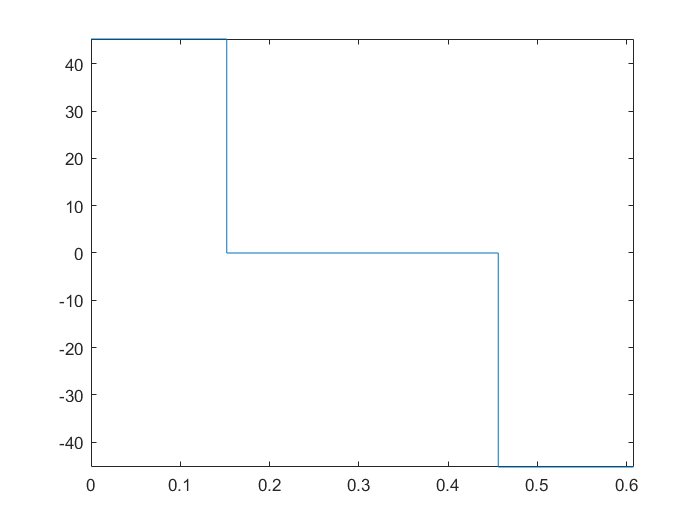

fplot(qa_piece2(1,:),[0,T_])

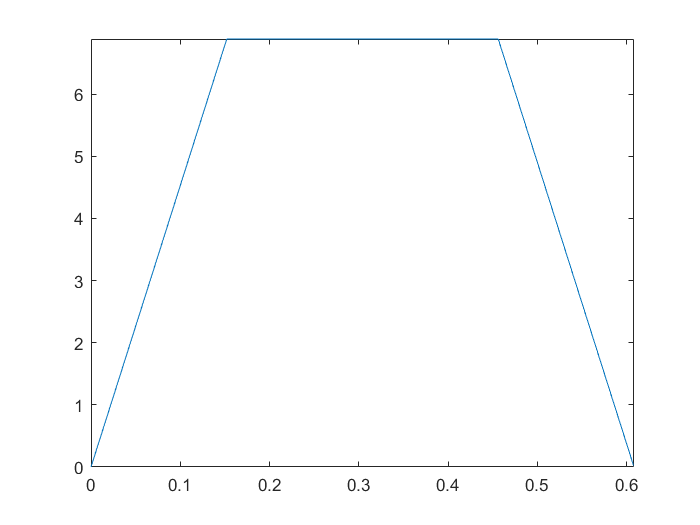

figure
fplot(qa_piece2(2,:),[0,T_])

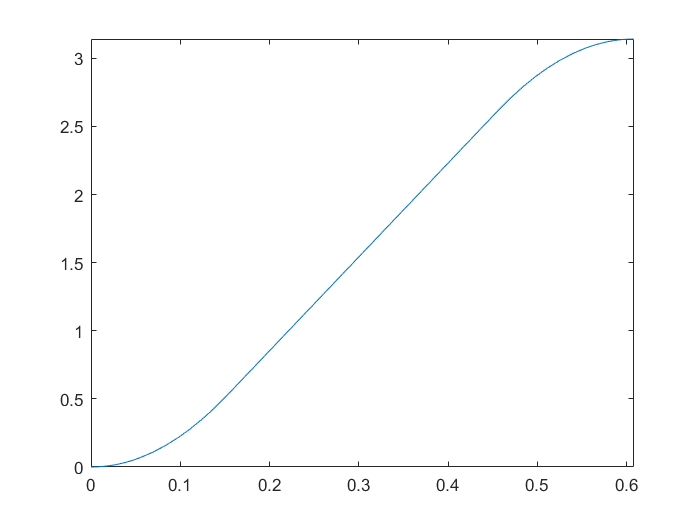

figure
fplot(qa_piece2(3,:),[0,T_])

figure
% [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% tau_2=int(qa_piece2,t)

## tau 2

tau_func=I_*qa_piece2(1,:)+tau_g_max_*sin(qa_piece2(3,:))

$$tau\_func = \left\{ \begin{array}{cl} \frac{981\,\sin\left(22.642500000016298145055770874023\,t^{2}\right)}{10}+150.95000000010865430037180582682 & \text{ if }t\in \left[0.0,0.15206775097840363741852343082428\right)\\ \frac{981\,\sin\left(6.8863881030556512996554374694824\,t-0.52359877559865708462893962860107\right)}{10} & \text{ if }t\in \left[0.15206775097840363741852343082428,0.4562032529356656596064567565918\right)\\ -\frac{981\,\sin\left(22.642500000016298145055770874023\,t^{2}-27.54555241222260519862174987793\,t+5.2359877559792948886752128601074\right)}{10}-150.95000000010865430037180582682 & \text{ if }t\in \left[0.4562032529356656596064567565918,0.60827100391361454967409372329712\right] \end{array}\right.$$

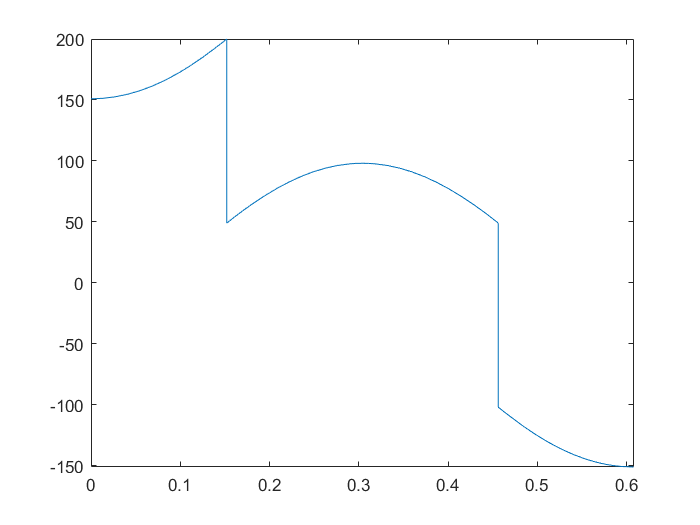

fplot(tau_func,[0,T_])

% figure
% fplot(qa_piece2(2,:),[0,T_])
% figure
% fplot(qa_piece2(3,:),[0,T_])